Best viewing experience is with output inline

4)

Below is a polynomial interpolation from data points from the function $f\left(x\right)=\frac{1}{1+x^2 }$  

for n = 4,6,8,10. We should see an example of runges phenomeon.

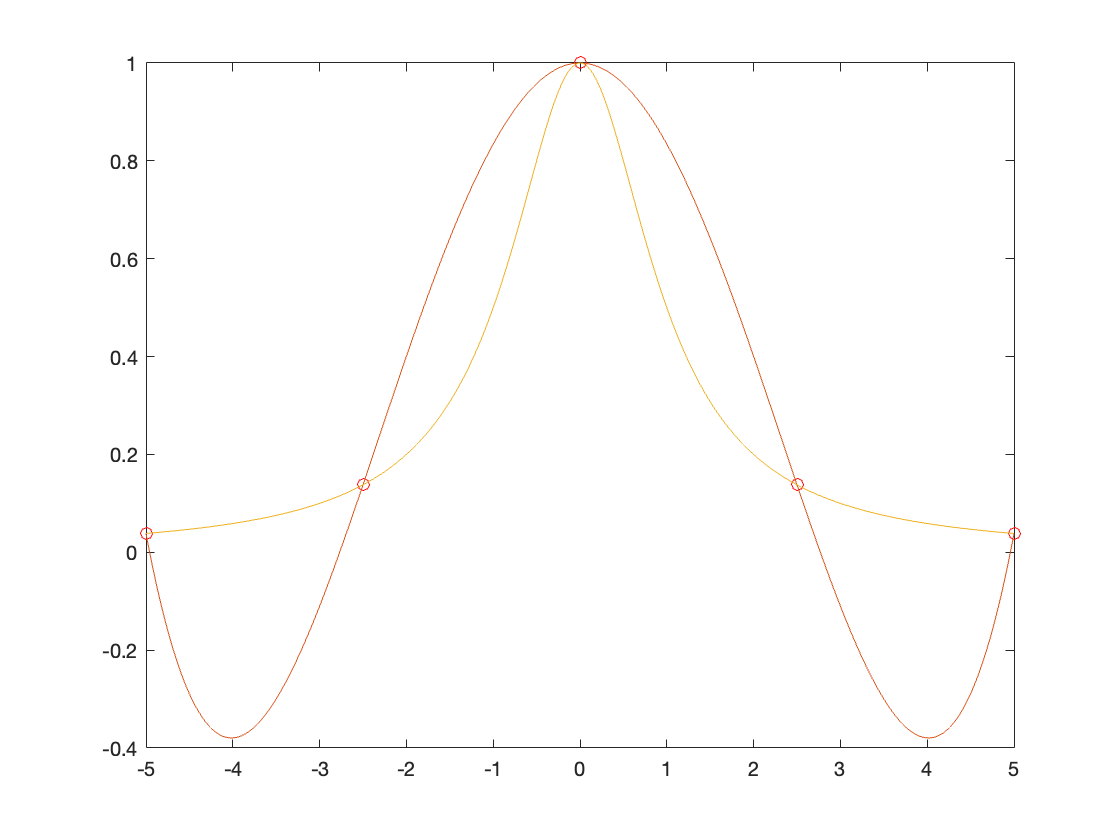

n = 4;
x = -5:10/n:5;
y =  1./(1+x.^2);
refinex = -5:.001:5;
refiney = polyval(polyfit(x,y,n),refinex); 
plot(x,y,'ro',refinex,refiney,'-',refinex,1./(1+refinex.^2))

daerror = max(abs(refiney-1./(1+refinex.^2)));
disp(daerror)

    0.4384



Above the graph for n = 4

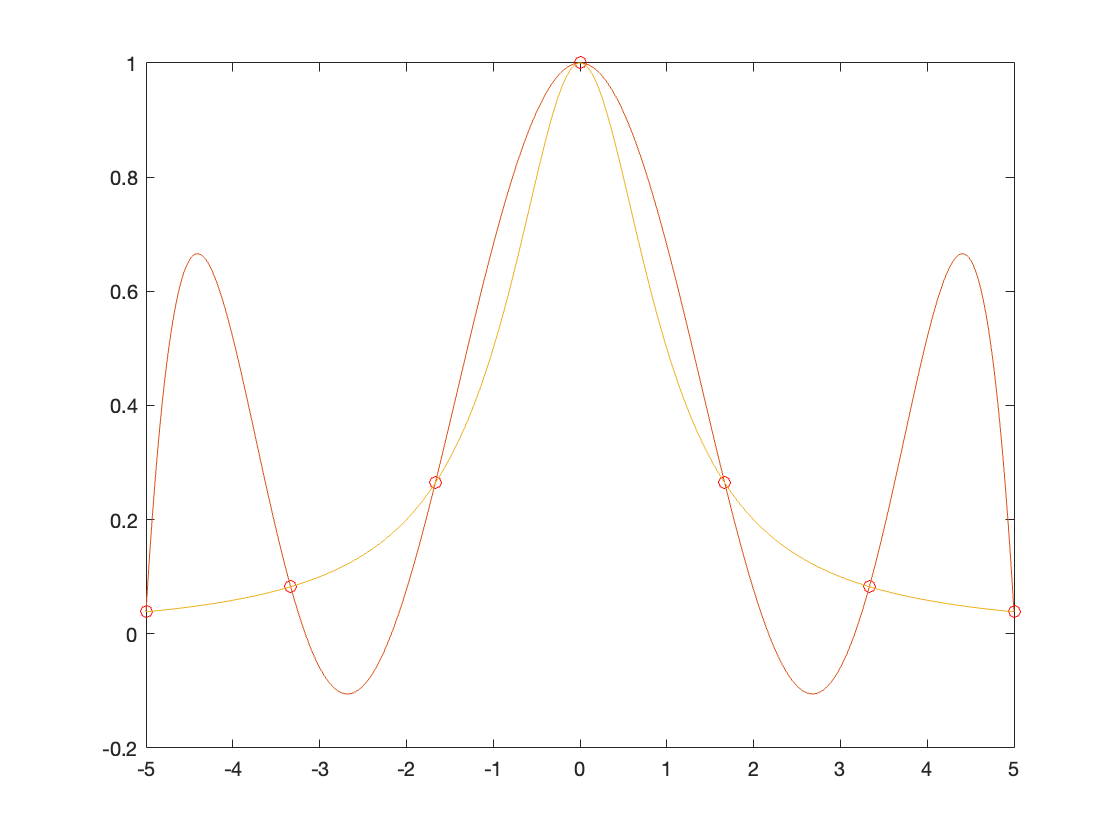

n = 6;
x = -5:10/n:5;
y =  1./(1+x.^2);
refinex = -5:.01:5;
refiney = polyval(polyfit(x,y,n),refinex); 
plot(x,y,'ro',refinex,refiney,'-',refinex,1./(1+refinex.^2))

daerror = max(abs(refiney-1./(1+refinex.^2)));
disp(daerror)

    0.6169



Above the graph for n = 6

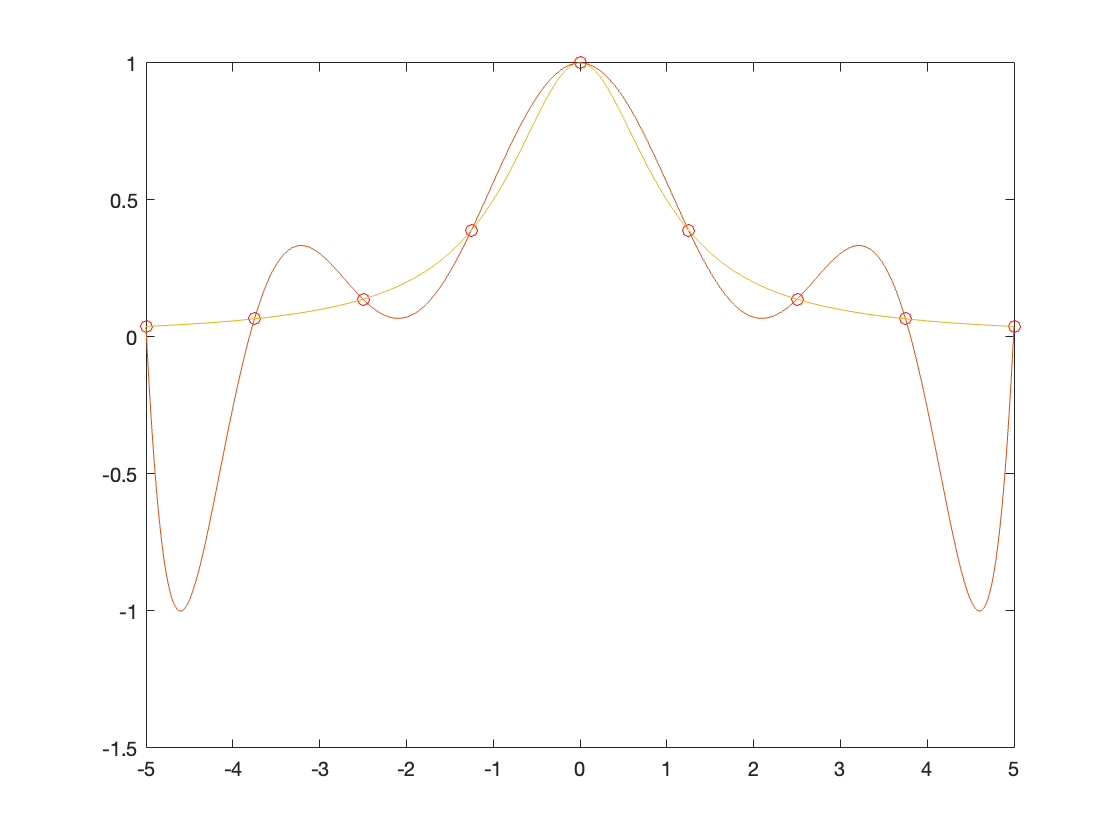

n = 8;
x = -5:10/n:5;
y =  1./(1+x.^2);
refinex = -5:.01:5;
refiney = polyval(polyfit(x,y,n),refinex); 
plot(x,y,'ro',refinex,refiney,'-',refinex,1./(1+refinex.^2))

daerror = max(abs(refiney-1./(1+refinex.^2)));
disp(daerror)

    1.0452



Above the graph for n =  8

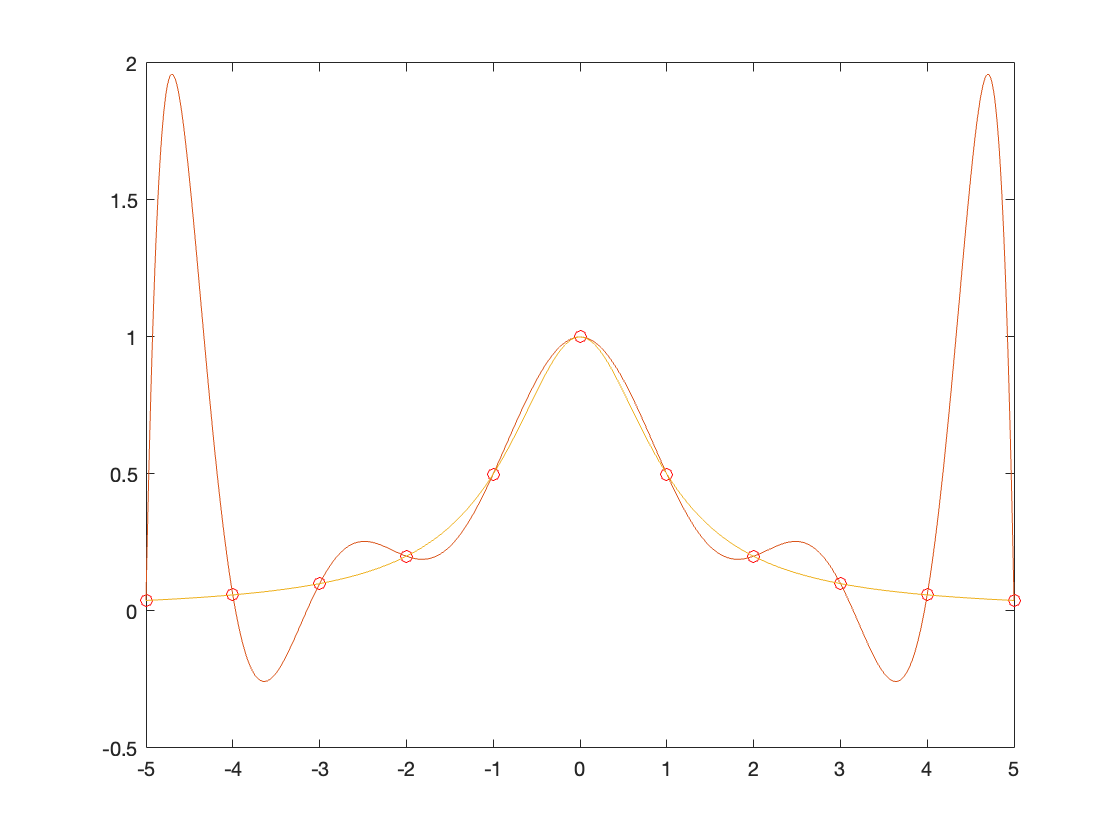

n = 10;
x = -5:10/n:5;
y =  1./(1+x.^2);
refinex = -5:.01:5;
refiney = polyval(polyfit(x,y,n),refinex); 
plot(x,y,'ro',refinex,refiney,'-',refinex,1./(1+refinex.^2))

daerror = max(abs(refiney-1./(1+refinex.^2)))

daerror = 1.9156

disp(daerror)

    1.9156



Above the graph for n =  10

Notice as our n gets bigger so does our error. It is clear to see that increasing our degree in polynomial does not always help in certain functions. When we attempt to bound the error $\;{\max \left|E\right.}_n f\left(x\right)\left|\le {\max \left|f\right.}^{n+1} \left(x\right)\right|\frac{h^{n+1} }{4\left(n+1\right)}$  the right fraction goes to zero as n heads to infinity but if the function isnt $C^n$ smooth then cannot conclude incresing our polynomial degree will increase accuracy.

5 ) Now if we use Chebyshev-Gauss-Lobatto nodes this problem should be migated. 

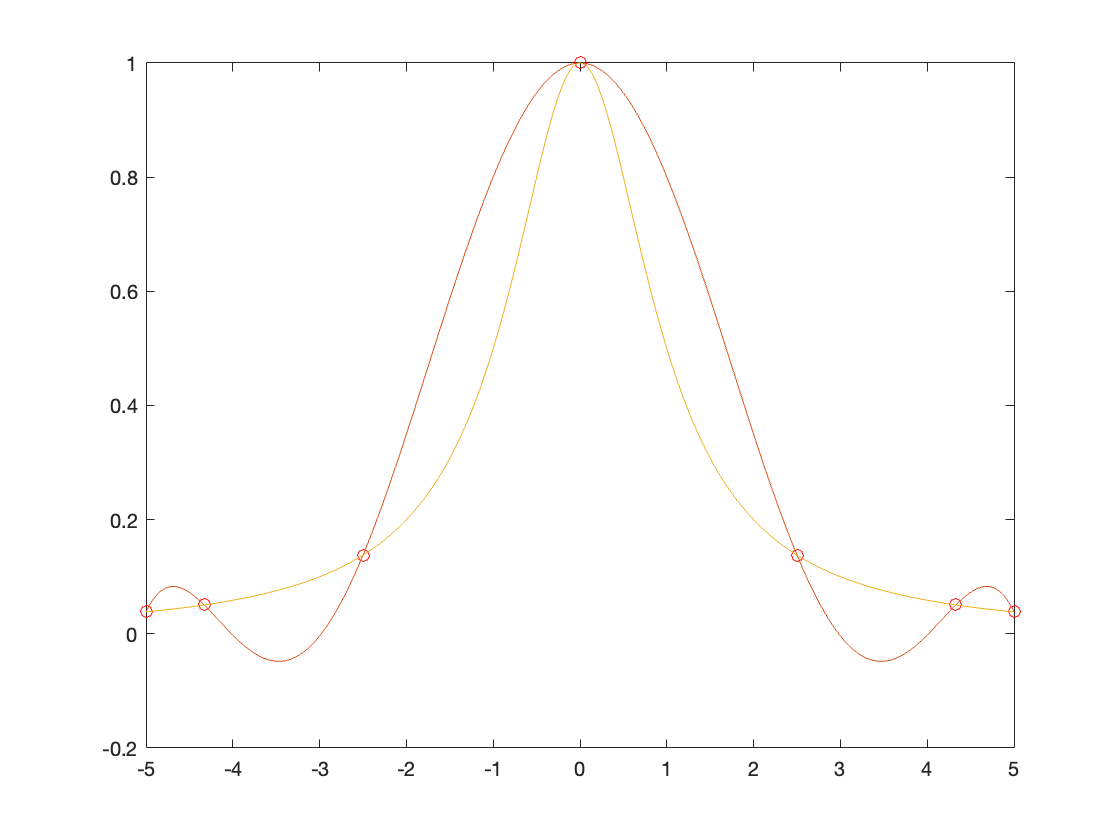

n = 6;
xc = -cos(pi*[0:n]/n);% CGL Nodes map our points to one that has more data points near the endpoints
a = -5; b= 5; % interval
x = (a+b)*0.5+(b-a)*xc*0.5;% the tranformation to new nodes
f= @(x) 1./(1+x.^2);
y = f(x);
c = polyfit(x,y,n);
x1 = linspace(-5,5,1000);
p = polyval(c,x1); 
f1 = f(x1); 
plot(x,y,'ro',x1,p,'-',x1,f(x1))

daerror = max(abs(p-f1));
disp(daerror)

    0.3112



Above is the n = 6 with CGL nodes. 

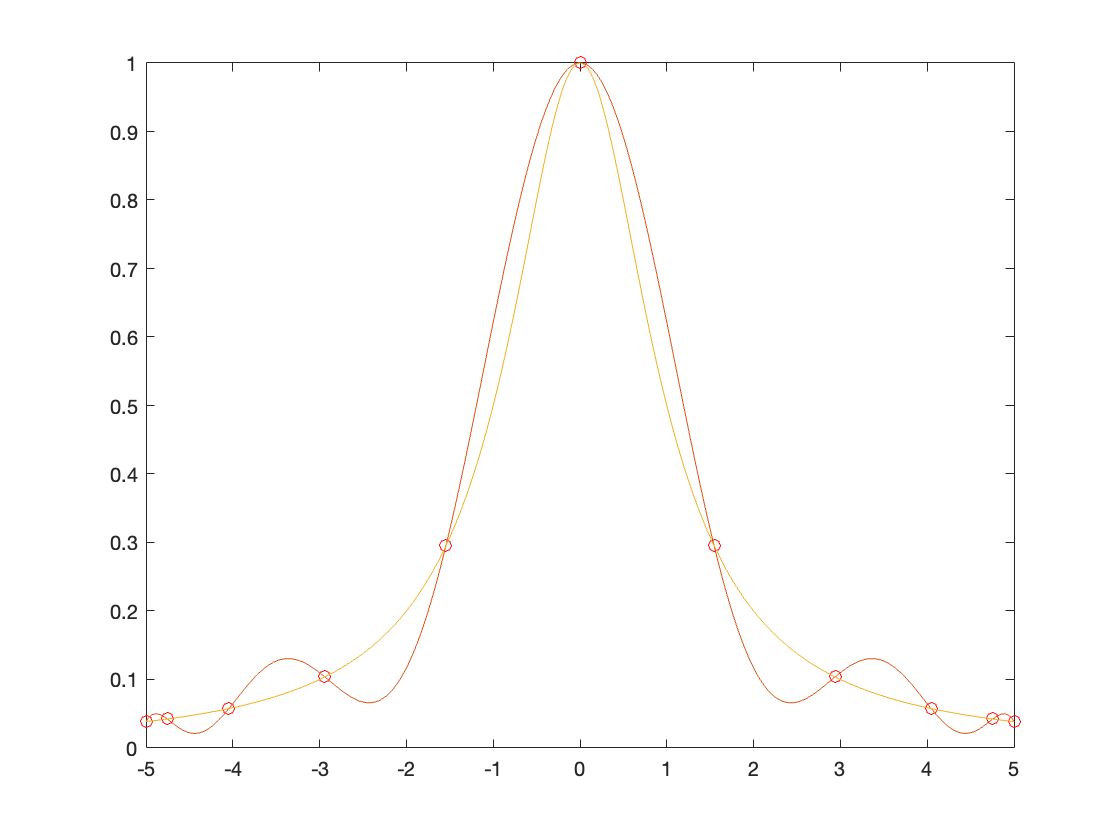

n = 10;
xc = -cos(pi*[0:n]/n);
a = -5; b= 5;
x = (a+b)*0.5+(b-a)*xc*0.5;
f= @(x) 1./(1+x.^2);
y = f(x);
c = polyfit(x,y,n);
x1 = linspace(-5,5,1000);
p = polyval(c,x1); 
f1 = f(x1); 
plot(x,y,'ro',x1,p,'-',x1,f1)

daerror = max(abs(p-f1));
disp(daerror)

    0.1322



Above is the n = 10 with CGL nodes. Clearly the oscillations from before have dissipated ridding us of Runge's phenemon. :) 		

6)	

Lets compare the Lagrange interpolation with a cubic spline interpolation with a smooth function.

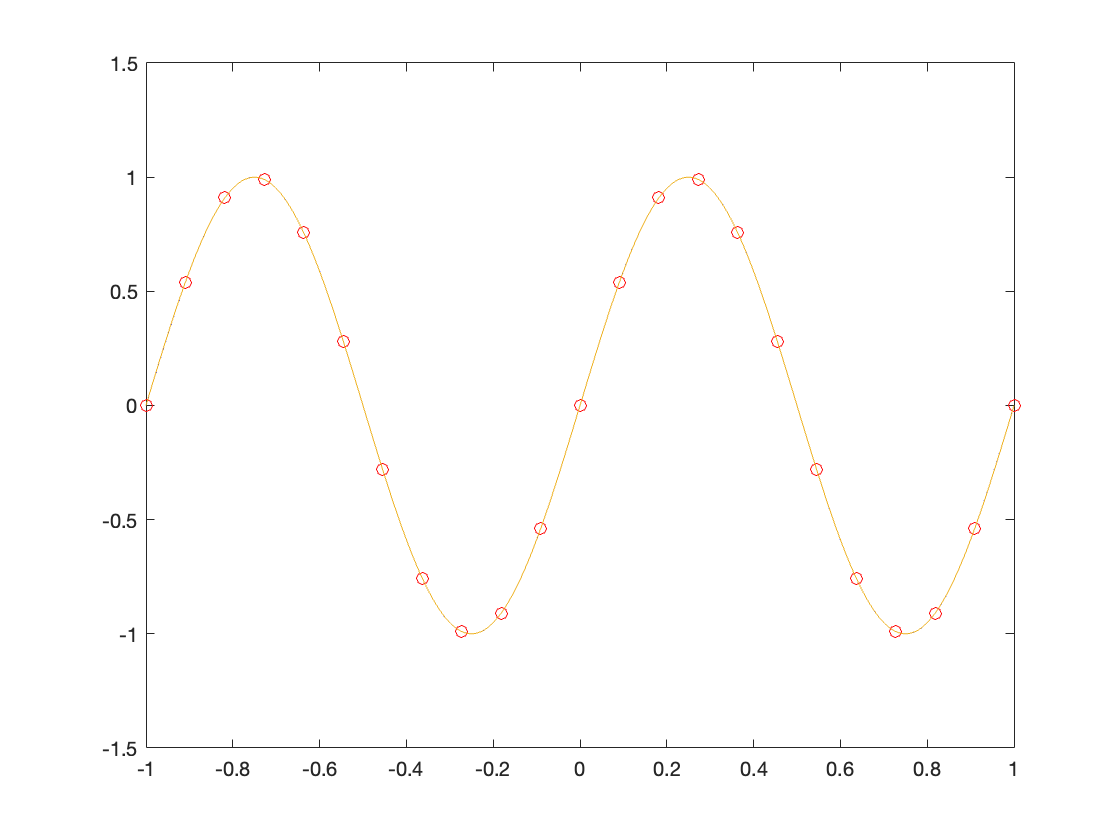

x6 = -1:2/22:1;
y6 = sin(2*pi*x6);
c6 = polyfit(x6,y6,22);
refinex6 = -1:.001:1;
refiney6 = polyval(c6,refinex6);
s6 = spline(x6,y6,refinex6);
plot(x6,y6,'ro',refinex6,refiney6,'b:',refinex6,s6,'-')

	 For a smooth function such as sin our approximation increases in accuary with the increase in n. Since the approximations are very close it is impossible to see the differences in the graph.

7)

Below we are adding some noise to our data to see how spline and polyfit perform with a little noise.

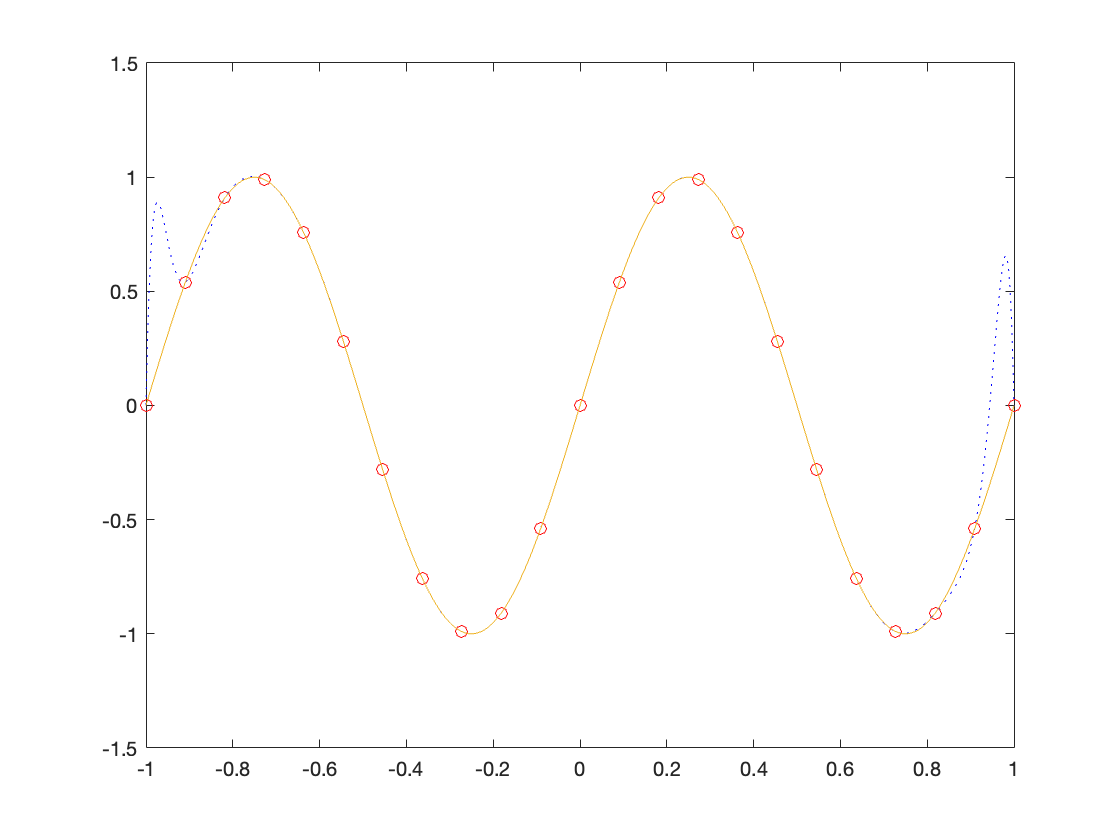

x7 = -1:2/22:1;
y7 = sin(2*pi*x7);
for n = 1:23
r = randn(1,1).*10^-4;
y7(n)= y7(n) + r;
end
c7 = polyfit(x7,y7,22);
refinex7 = -1:.001:1;
refiney7 = polyval(c7,refinex7);
s7 = spline(x7,y7,refinex7);
plot(x7,y7,'ro',refinex7,refiney7,'b:',refinex7,s7,'-')

As we see above there is a little difference but is still pretty accurate as we see. Our cubic spline did equally as well with the noiseless data while the polyfit might have been overfitted but still doing well.

8)

Below we will use the fft matlab method to find frequnecy and amplitudes of the signal $f\left(t\right)=0\ldotp 3\mathrm{sin}\left(t\right)+\mathrm{cos}\left(4t\right)$ on $t\;\epsilon \;\left\lbrack 0,2\pi \right\rbrack$

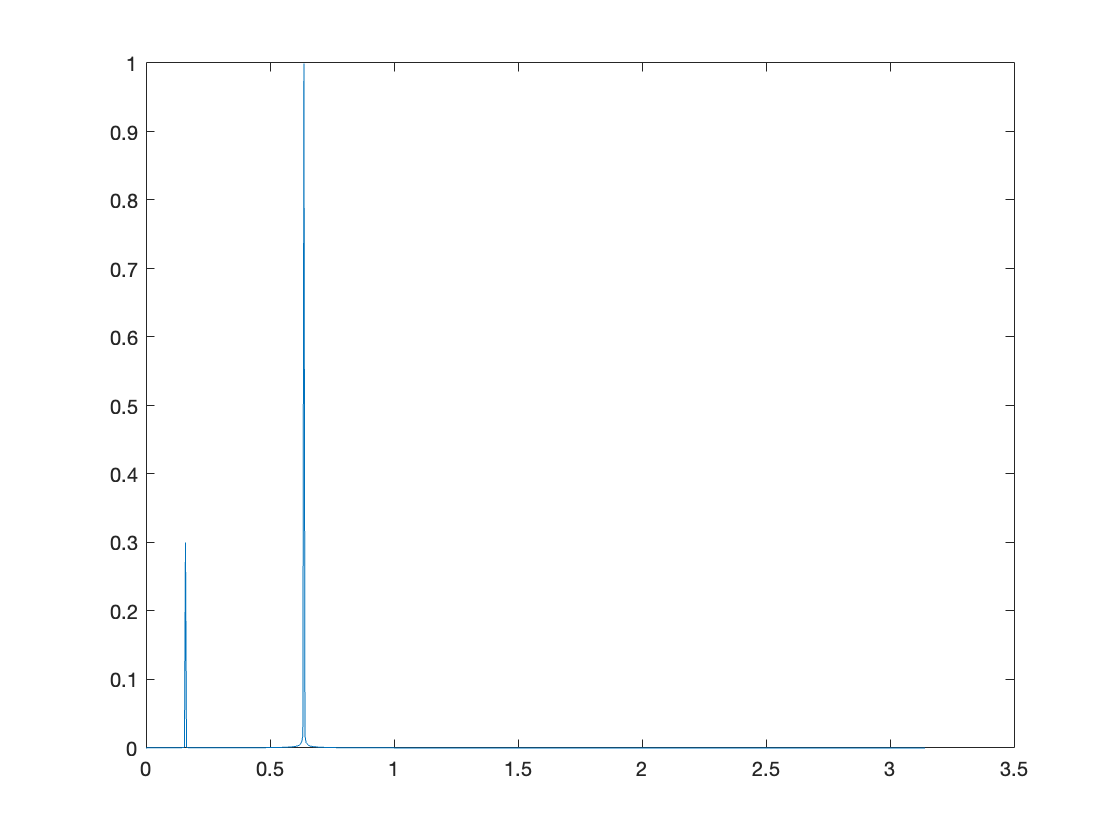

Fs = 2*pi;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
L = 1500;             % Length of signal
t = (0:L-1)*T;        % Time vector
S = 0.3*sin(t) + cos(4*t);
f = Fs*(0:(L/2))/L;
Y = fft(S);
P2 = abs(Y/L);
P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
plot(f,P1) 

The graph above shows the amplitudes with the maxes of .3 and 1 which is exactly it!